# Permutations visualization

Elaborated by Natanael Bolson

Supervised by Prof. Tad Patzek and Maxim Yutkin

EGG-ANPERC-KAUST 06/2021

Description: Plot all the permutations, shows the histogram distribution of the data comparing optimum with the mean values

clc
clear 
close all

## Load Data

load ../Data/Tab_Indicators.mat 
load ../Data/Clean_Mirrors.mat % Here load the variable L to clean

% Change the number to get a different country
% Check Tab for reference
n=22;
Country=Tab_Indicators.Labels(n)

Country = 1×1 cell array
    {'Brazil'}


## Figure showing all the permutations

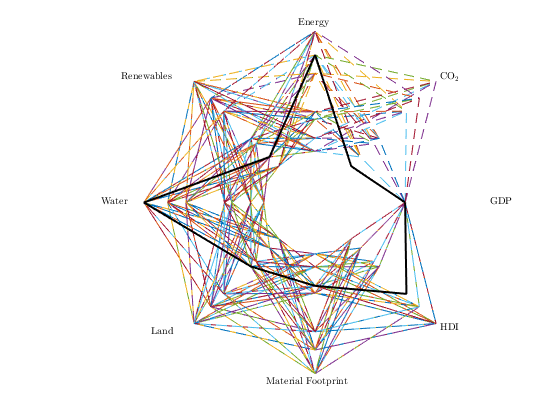

X=[0,45,90,135,180,225,270,315,360]*pi/180;

% Optimized
Indicators=[Tab_Indicators.GDP_N(n),Tab_Indicators.CO2_N(n),...
      Tab_Indicators.Exp_N(n),Tab_Indicators.Ren_N(n),...
      Tab_Indicators.Water_N(n),Tab_Indicators.Land_N(n),...
      Tab_Indicators.Mat_N(n),Tab_Indicators.HDI_N(n),Tab_Indicators.GDP_N(n)];
Y= Indicators(2:8);
    P=perms(Y);

% Eliminate mirrors
P(find(isnan(L)),:)=[]; 

   for m=1:size(P,1)
 
        [x,y]=pol2cart(X,[Indicators(1) P(m,:) Indicators(1)]);
        Area(m)=polyarea(x,y);
        figure (1)
        plot(x,y,'--','LineWidth',0.5)
        hold on
        
   end
   
   for n=1:size(Indicators,1)
    [x,y] = pol2cart(X,Indicators(n,:));
    Area_Opt(n)=polyarea(x,y);
   end
   
   plot(x,y,'k','LineWidth',2)
   text(1.025,0,'GDP','interpreter','latex')
   text(sqrt(2)/2+0.025,sqrt(2)/2+.025,'$$\mathrm{CO_2}$$','interpreter','latex')
   text(-0.1,1.05,'Energy','interpreter','latex')
   text(-sqrt(2)/2-0.425,sqrt(2)/2+0.025,'Renewables','interpreter','latex')
   text(-1.25,0,  'Water','interpreter','latex')
   text(-sqrt(2)/2-0.25,-sqrt(2)/2-0.05,'Land','interpreter','latex')
   text(0-0.285,-1.05,'Material Footprint','interpreter','latex')
   text(sqrt(2)/2+0.025,-sqrt(2)/2-0.025,'HDI','interpreter','latex')
   axis equal
   axis off

## Area values

Area_Opt

Area_Opt = 0.9433

A_Median=median(Area)

A_Median = 1.0125

A_Mean=mean(Area)

A_Mean = 1.0120

A_Max= max(Area)

A_Max = 1.1258

A_min= min(Area)

A_min = 0.9089

A_CV=std(Area)/A_Mean

A_CV = 0.0462

## Histograms

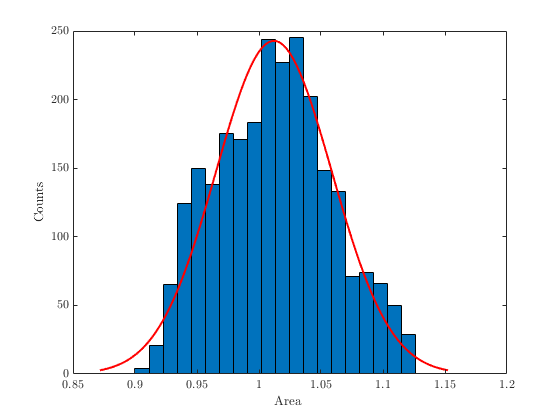

figure
histfit(Area,20,'normal')
xlabel('Area ',"Interpreter","latex")
ylabel('Counts',"Interpreter","latex")
set(gca,'Fontsize',12,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

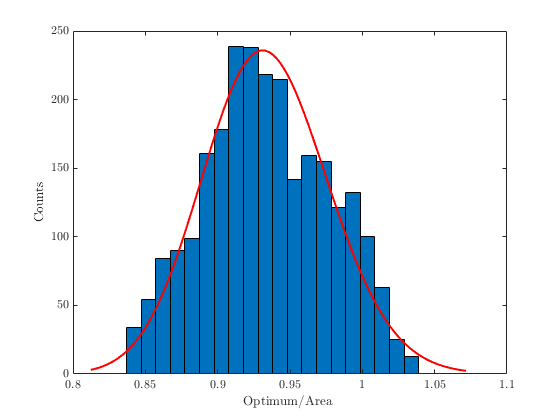


figure
histfit(Area_Opt./Area,20,'lognormal')
xlabel('Optimum/Area ',"Interpreter","latex")
ylabel('Counts',"Interpreter","latex")
set(gca,'Fontsize',12,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% Print Maximum and Minimum
MI=find(Area==min(Area),1);
MA=find(Area==max(Area),1);
Indicators;
P_min=P(MI,:);
for n=1:7
   I_Mi(n)= find(Indicators==P_min(n),1);
end
I_Mi=[1,I_Mi(1:end)];
[ii,jj,kk]=unique(I_Mi);
out=ii(histc(kk,1:numel(ii))>1);
for n=1:length(out)
 Rep=find(I_Mi==out(n));
 Eq=find(Indicators==Indicators(out(n)));
 for m=2:length(Rep)
     I_Mi(Rep(m))=Eq(m);
 end
end 
I_Mi;
P_max=P(MA,:);
  for n=1:7
   I_Ma(n)= find(Indicators==P_max(n),1);
end
I_Ma=[1,I_Ma(1:end)];
[ii,jj,kk]=unique(I_Ma);
out=ii(histc(kk,1:numel(ii))>1);
for n=1:length(out)
 Rep=find(I_Ma==out(n));
 Eq=find(Indicators==Indicators(out(n)));
 for m=2:length(Rep)
     I_Ma(Rep(m))=Eq(m);
 end
end 
I_Ma;

## Eliminate repeated index

Label={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
    'Mat. F.','HDI'};
LMa=Label(I_Ma);
LMi=Label(I_Mi);
y2=ones(1,9);
Cmin=[0.0196    0.4392    0.6902];
[x,y] = pol2cart(X,Indicators(1,:));
[x2,y2] = pol2cart(X,y2);
[x3,y3] = pol2cart(X,[Indicators(1) P_max Indicators(1)]);
[x4,y4] = pol2cart(X,[Indicators(1) P_min Indicators(1)]);

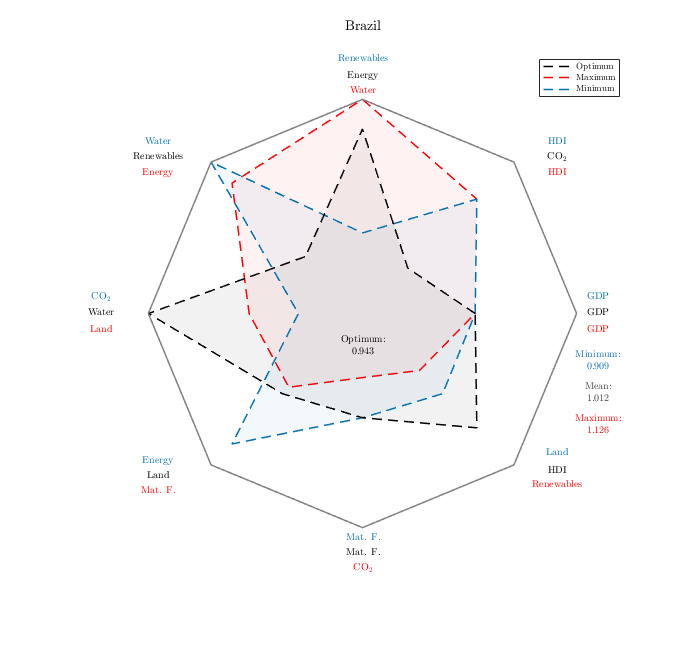


figure('Name','Proposed')
   plot(x,y,'--k','LineWidth',1.5)
   hold on
   fill(x,y,'k','facealpha',0.05,'edgecolor','none','HandleVisibility',"off")
   plot(x3,y3,'--r','LineWidth',1.5)
   fill(x3,y3,'r','facealpha',0.05,'edgecolor','none','HandleVisibility',"off")
   plot(x4,y4,'--','Color',Cmin,'LineWidth',1.5)
   fill(x4,y4,Cmin,'facealpha',0.05,'edgecolor','none','HandleVisibility',"off")
   plot(x,y,'--k','LineWidth',1.5)
   plot(x2,y2,'Color',[0.5 0.5 0.5],'LineWidth',1.5)

% Optimum
XLP=[1.1,sqrt(2)/2+0.2,-0.,-sqrt(2)/2-0.25,-1.22,-sqrt(2)/2-0.25,0,sqrt(2)/2+0.2];
YLP=[0,sqrt(2)/2+.025,1.11,sqrt(2)/2+0.025,0,-sqrt(2)/2-0.05,-1.12,-sqrt(2)/2-0.03,];
text(XLP,YLP,Label,'HorizontalAlignment',"center",'interpreter','latex')
% Max
YLMa=[-0.075,sqrt(2)/2-.05,1.04,sqrt(2)/2-0.05,-0.075,-sqrt(2)/2-0.12,-1.19,-sqrt(2)/2-0.095];
text(XLP,YLMa,LMa,'Color','r','HorizontalAlignment',"center",'interpreter','latex')
% Min
YLMi=[0.075,sqrt(2)/2+.095,1.19,sqrt(2)/2+0.095,0.075,-sqrt(2)/2+0.02,-1.05,-sqrt(2)/2+0.055,];
text(XLP,YLMi,LMi,'Color',Cmin,'HorizontalAlignment',"center",'interpreter','latex')

% Areas
text(1.1,-0.22,{'Minimum:' round(A_min,3)},'Color',Cmin,'HorizontalAlignment',"center",'interpreter','latex')
text(1.1,-0.52,{'Maximum:';round(A_Max,3)},'Color','r','HorizontalAlignment',"center",'Interpreter','latex')
text(0,-0.15,{'Optimum:';round(Area_Opt,3)},'Color','k','HorizontalAlignment',"center",'interpreter','latex')
text(1.1,-0.37,{'Mean:';round(A_Mean,3)},'Color',[0.25 0.25 0.25],'HorizontalAlignment',"center",'interpreter','latex')
% text(00,-0.,Country,'Color','k','HorizontalAlignment',"center",'FontSize',12,'interpreter','latex')
title(Country,'Position', [0, 1.3, 0],'Fontsize',14,'Interpreter','latex')
legend('Optimum','Maximum','Minimum','Interpreter','latex','Location',"best")
axis equal
axis off
set(gcf,'Position',[100 100 700 650])

filename=append(char(Country), '.png');
% print('-dpng','-r400',filename)
